# Bicycle model Simulink experiment

Doc : https://fr.mathworks.com/help/robotics/ug/plan-path-for-a-bicycle-robot-in-simulink.html

clear; clc;

### Load environment

load exampleMaps.mat
startLoc = [5 5];
goalLoc = [35 22];
open_system('pathPlanningBicycleSimulinkModel.slx')

### Run model

simulation = sim('pathPlanningBicycleSimulinkModel.slx');

### Visualise everything

#### Define map layout (walls, ...)

map = binaryOccupancyMap(complexMap)

map =   binaryOccupancyMap with properties:

   mapLayer Properties
              LayerName: 'binaryLayer'
               DataType: 'logical'
           DefaultValue: 0
    GridLocationInWorld: [0 0]
      GridOriginInLocal: [0 0]
     LocalOriginInWorld: [0 0]
             Resolution: 1
               GridSize: [41 52]
           XLocalLimits: [0 52]
           YLocalLimits: [0 41]
           XWorldLimits: [0 52]
           YWorldLimits: [0 41]


#### Get all robot poses

robotPose = simulation.BicyclePose

robotPose =     5.0000    5.0000         0
    5.0000    5.0000    0.0002
    5.0001    5.0000    0.0012
    5.0006    5.0000    0.0062
    5.0031    5.0000    0.0313
    5.0156    5.0012    0.1569
    5.0707    5.0293    0.7849
    5.0979    5.0794    1.3638
    5.1001    5.0995    1.5348
    5.0999    5.1198    1.6162


#### Print map of movements

% numRobots = size(robotPose, 2) / 3;
% thetaIdx = 3;
% 
% % Translation
% xyz = robotPose;
% xyz(:, thetaIdx) = 0;
% 
% % Rotation in XYZ euler angles
% theta = robotPose(:,thetaIdx);
% thetaEuler = zeros(size(robotPose, 1), 3 * size(theta, 2));
% thetaEuler(:, end) = theta;
% 
% for k = 1:size(xyz, 1)
%     show(map)
%     hold on;
%     
%     % Plot Start Location
%     plotTransforms([startLoc, 0], eul2quat([0, 0, 0]))
%     text(startLoc(1), startLoc(2), 2, 'Start');
%     
%     % Plot Goal Location
%     plotTransforms([goalLoc, 0], eul2quat([0, 0, 0]))
%     text(goalLoc(1), goalLoc(2), 2, 'Goal');
%     
%     % Plot Robot's XY locations
%     plot(robotPose(:, 1), robotPose(:, 2), '*b')
%     
%     % Plot Robot's pose as it traverses the path
%     quat = eul2quat(thetaEuler(k, :), 'xyz');
%     plotTransforms(xyz(k,:), quat, 'MeshFilePath',...
%         'groundvehicle.stl');
%     
%     pause(0.01)
%     hold off;
% end

show(map)
hold on;
plot(robotPose(:,1), robotPose(:,2), "-b")
[y_max, x_max] = size(complexMap)

y_max = 41

x_max = 52

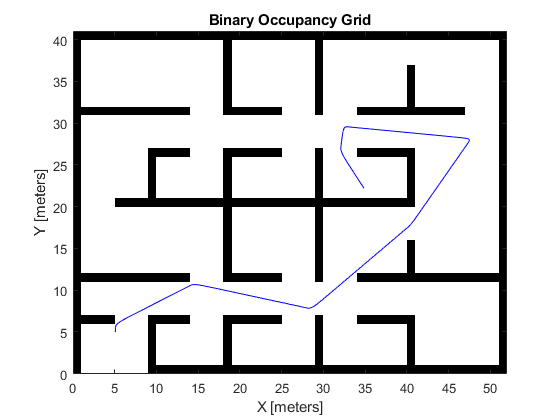

ylim([0, y_max])
xlim([0, x_max])